# Pemrograman Dasar MATLAB

## Variabel

Aturan penulisan variabelnya pun sama dengan bahasa pemrograman lainnya, yaitu bersifat *case sensitive *dimana diawali dengan huruf dan selanjutnya bisa menggunakan gabungan huruf-angka atau symbol.

var1 = [1 2 3]

var1 =      1     2     3


## Operator

Operator Aritmatika

a = [1 2 3];
b = [2 3 4];
penjumlahan     = a + b

penjumlahan =      3     5     7


pengurangan     = b - a

pengurangan =      1     1     1


perkalian       = a .* b        % perkalian element by element

perkalian =      2     6    12


pembagian_kanan = a ./ b

pembagian_kanan =     0.5000    0.6667    0.7500


pembagian_kiri  = a .\ b        % sama saja dengan b ./ a

pembagian_kiri =     2.0000    1.5000    1.3333


perpangkatan    = a .^ 2

perpangkatan =      1     4     9



a = [2 2 2;4 4 4];
b = [2 2;4 4;8 8];
perkalian_m     = a*b           % perkalian matriks

perkalian_m =     28    28
    56    56



a = pascal(3);
b = magic(3);
pembagian_r_m   = a/b           % C = AB^-1 = A/B

pembagian_r_m =     0.0667    0.0667    0.0667
   -0.0333    0.4667   -0.0333
   -0.1528    1.0556   -0.2361


pembagian_l_m   = a\b           % C = inv(A)B = A\B 

pembagian_l_m =     19    -3    -1
   -17     4    13
     6     0    -6


Fungsi dasar

abs(-1)

ans = 1

sqrt(4)

ans = 2

exp(10)

ans = 2.2026e+04

log(100)

ans = 4.6052

log10(100)

ans = 2

log2(8)

ans = 3

Operator Relasional

0 == 1

ans = logical
   0


0 ~= 1

ans = logical
   1


0 < 1

ans = logical
   1


0 > 1

ans = logical
   0


0 >= 1

ans = logical
   0


0 <= 1

ans = logical
   1


Operator Logika

(0 == 1) & (0 ~= 1)

ans = logical
   0


(0 == 1) | (0 ~= 1)

ans = logical
   1


~(0 == 1)

ans = logical
   1


xor((0 == 1),(0 ~= 1))

ans = logical
   1


## Tipe Data

Numerik

x = 2 + 3i           % complex number

x = 2.0000 + 3.0000i

real(x)

ans = 2

imag(x)

ans = 3

Characters dan Strings

character = 'test'

character = 'test'

strings   = "test"

strings = "test"


% Fungsi untuk menampilkan teks
disp(character)

test



% Fungsi fprintf
A1 = [9.9, 9900];
A2 = [8.8,  7.7 ; 8800, 7700];
formatSpec = 'X is %4.2f meters or %8.3f mm\n';
fprintf(formatSpec,A1,A2)

X is 9.90 meters or 9900.000 mm
X is 8.80 meters or 8800.000 mm
X is 7.70 meters or 7700.000 mm



% Fungsi sprintf
A = 1/eps;
sprintf('%0.5e',A)

ans = '4.50360e+15'


% Fungsi Input
%input('Masukkan teks: ','s')

Tables

LastName = {'Sanchez';'Johnson';'Li';'Diaz';'Brown'};
Age = [38;43;38;40;49];
Smoker = logical([1;0;1;0;1]);
Height = [71;69;64;67;64];
Weight = [176;163;131;133;119];
BloodPressure = [124 93; 109 77; 125 83; 117 75; 122 80];
T = table(LastName,Age,Smoker,Height,Weight,BloodPressure)

T = 5×6 table
    LastName     Age    Smoker    Height    Weight    BloodPressure
    _________    ___    ______    ______    ______    _____________

    'Sanchez'    38     true        71       176       124     93  
    'Johnson'    43     false       69       163       109     77  
    'Li'         38     true        64       131       125     83  
    'Diaz'       40     false       67       133       117     75  
    'Brown'      49     true        64       119       122     80  


Structures

data.x = linspace(0,2*pi);
data.y = sin(data.x);
data.title = 'y = sin(x)'

data = struct with fields:
        x: [1×100 double]
        y: [1×100 double]
    title: 'y = sin(x)'


Cell Arrays

C = {1,2,3;'text',rand(5,10,2),{11; 22; 33}}

C = 2×3 cell array
    {[   1]}    {[          2]}    {[     3]}
    {'text'}    {5×10×2 double}    {3×1 cell}


## Matriks

Matriks (manual input)

mat1 = [1 2 3;4 5 6]

mat1 =      1     2     3
     4     5     6


Matriks khusus

zeros(3,3)         % matriks nol

ans =      0     0     0
     0     0     0
     0     0     0


ones(3,3)          % matriks satu

ans =      1     1     1
     1     1     1
     1     1     1


eye(3,3)           % matriks identitas

ans =      1     0     0
     0     1     0
     0     0     1


magic(3)           % matriks bujur sangkar ajaib

ans =      8     1     6
     3     5     7
     4     9     2


pascal(3)          % matriks simetri

ans =      1     1     1
     1     2     3
     1     3     6


rand(3,3)          % matriks acak berdasarkan distribusi uniform

ans =     0.8152    0.2441    0.8522
    0.6384    0.8034    0.4673
    0.4483    0.8240    0.9707


randn(3,3)         % matriks acak berdasarkan distribusi normal

ans =     0.9197    0.5836    1.0748
   -1.8081   -0.1162    1.7022
   -1.2653   -0.1438    0.3912


randi(3,3)         % matriks acak bertipe integer

ans =      2     1     2
     3     1     1
     2     1     1


## Grafik

Grafik 2D

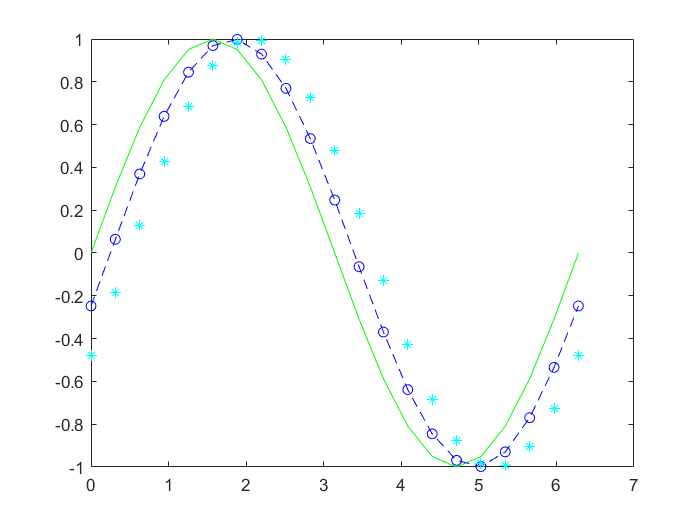

x = 0:pi/10:2*pi;
y1 = sin(x);
y2 = sin(x-0.25);
y3 = sin(x-0.5);
plot(x,y1,'g',x,y2,'b--o',x,y3,'c*')

Grafik 3D

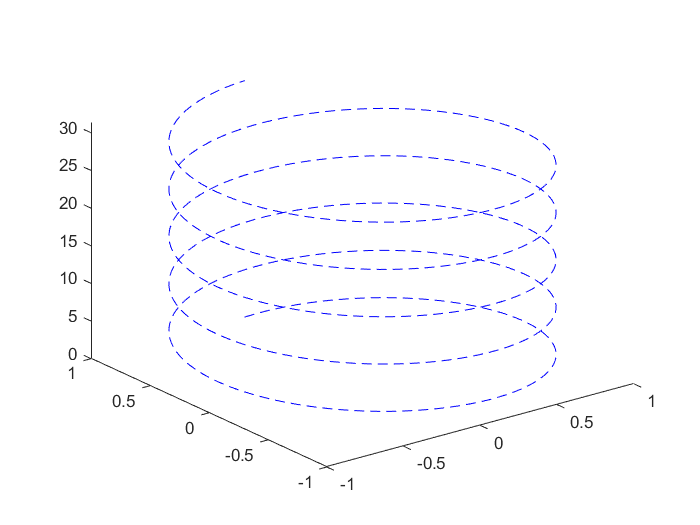

t = 0:pi/50:10*pi;
st = sin(t);
ct = cos(t);
plot3(st,ct,t,'b--')

Bar

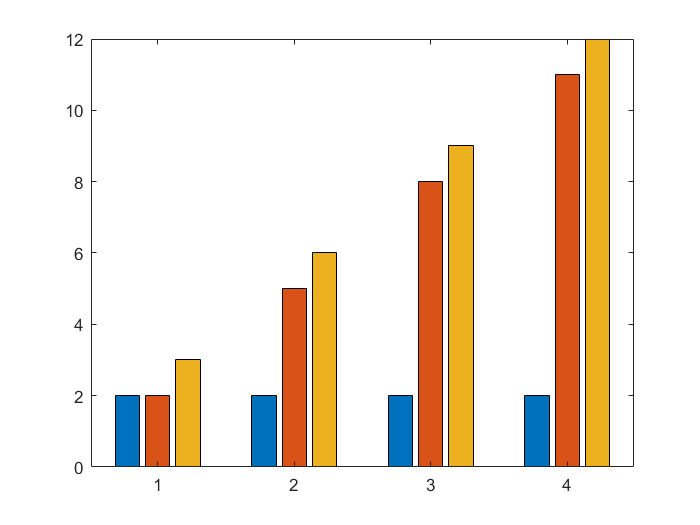

y = [2 2 3; 2 5 6; 2 8 9; 2 11 12];
bar(y)             % vertical

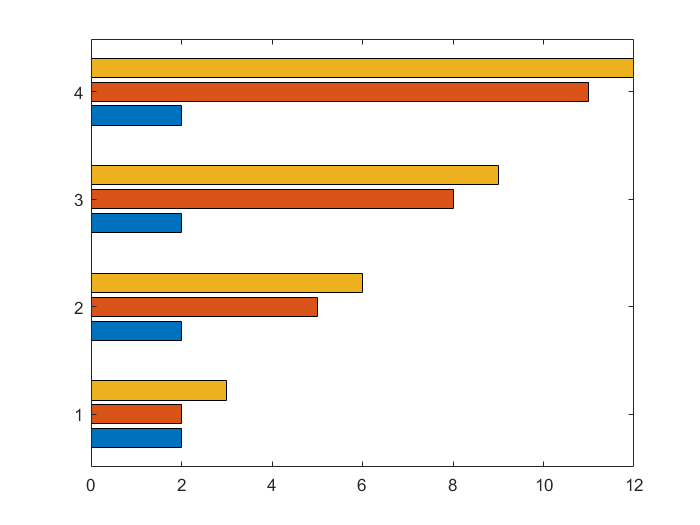

barh(y)            % horizontal

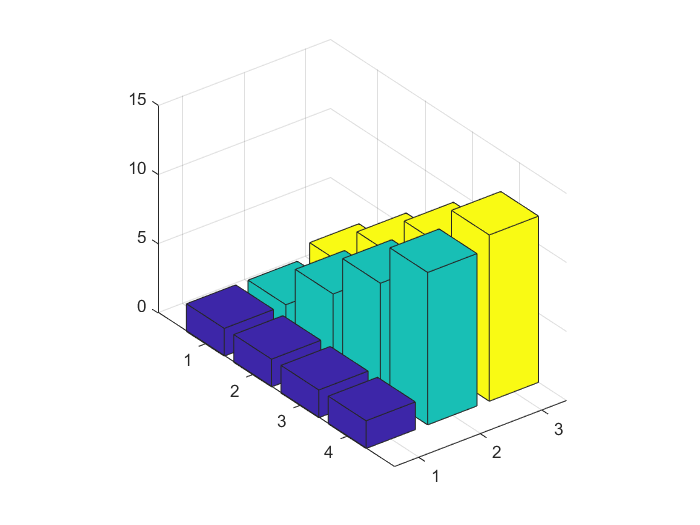

bar3(y)            % vertical

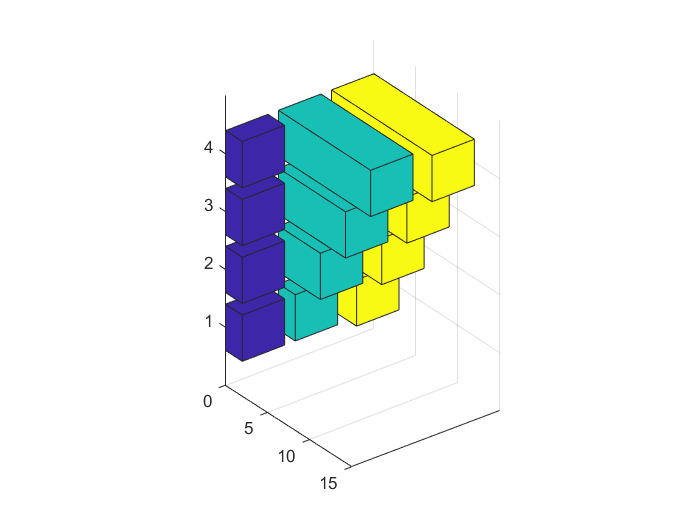

bar3h(y)           % horizontal

Pie Chart

Fungsi pie digunakan untuk menampilkan data secara persentase, dimana setiap elemen data akan dibandingkan dengan penjumlahan seluruh data yang ada.

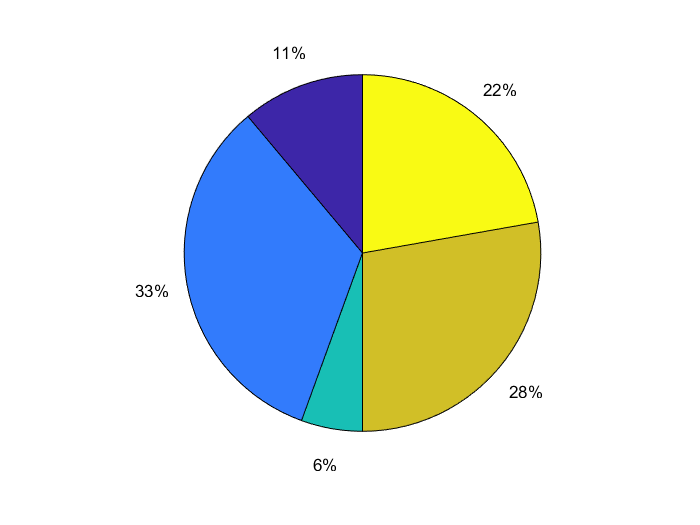

X = [1 3 0.5 2.5 2];
pie(X)      %untuk versi 2D

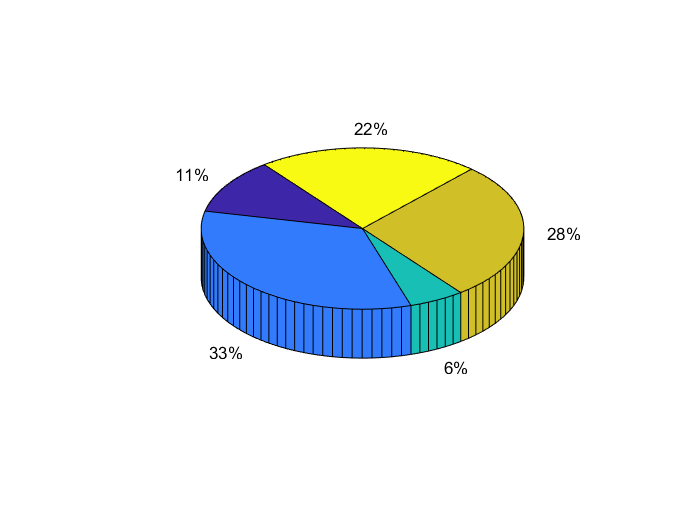

pie3(X)     %untuk versi 3D

Stem

Fungsi stem cocok digunakan untuk data dalam bentuk diskrit.

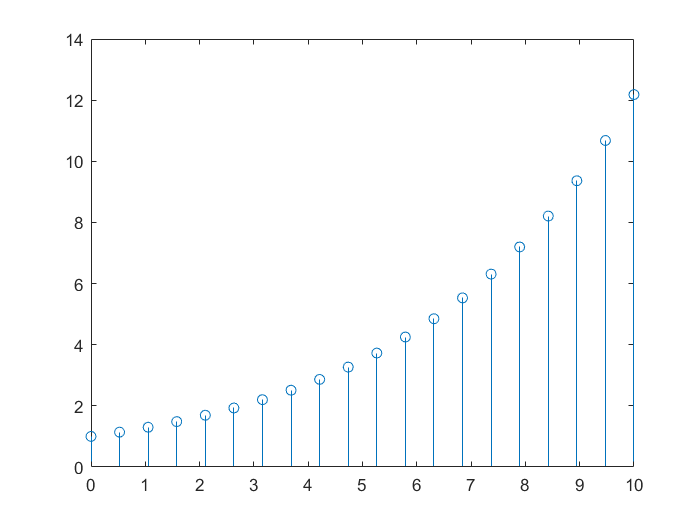

X = linspace(0,10,20)';
Y = (exp(0.25*X));
stem(X,Y)

## Pernyataan Kontrol (Control Statement)

if, else dan else if

nilai = 70

nilai = 70

if (nilai > 80)
    disp('Sangat baik')
elseif (nilai < 60)
    disp('Buruk')
else
    disp('Cukup')
end

Cukup


while

fak = 1;
i = 1;
while (i<5)
    fak = fak*i;
    i = i+1;
end
fprintf('faktorial dari 5 adalah: %d \n',fak)

faktorial dari 5 adalah: 24 


for

temp = 0;
for i = 1:10
    temp = temp + i;
end
sprintf('jumlah 10 bilangan asli pertama adalah: %d',temp)

ans = 'jumlah 10 bilangan asli pertama adalah: 55'

continue dan break

% statemnent continue
for i = 1:10
    if (i == 5 || i == 7)
        continue
    end
    disp(i);
end

     1

     2

     3

     4

     6

     8

     9

    10




% statement break
for i = 1:10
    if (i == 5)
        break
    end
    disp(i);
end

     1

     2

     3

     4



switch, case, otherwise

n = -1;
switch n
    case -1
        disp('negative one')
    case 0
        disp('zero')
    case 1
        disp('positive one')
    otherwise
        disp('other value')
end

negative one


try, catch

try
    a = notaFunction(5,6)
catch
    disp('Fungsi tidak ditemukan')
end

Fungsi tidak ditemukan


return

n = 1;
while n < 5
    disp(n);
    if (mod(n,2) == 0)
        disp('Bilangan Genap');
        return;
    end
    n = n+1;
end

     1

     2



Bilangan Genap


## Fungsi

fungsiku(3,4)   % memanggil fungsi

Definisi fungsi:

function c = fungsiku(a,b)
c = sqrt(a.^2 + b.^2);
end